## (Self note) mpc_2.mlx differs from mpc.mlx by allowing floating x and y in our trajectories. We're still using rounded x and y with lookup table instead of using interpolation

clear all;
clc;
clf;

## Elevation, Soil, and Visibility data

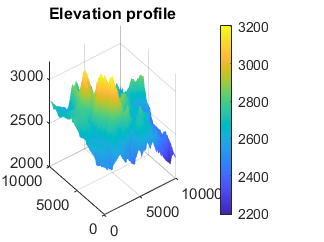

global x_min x_max y_min y_max;

ZM = load('map.txt');
soil = load('soil.txt');
vis = load('visibility.txt');

xv = [0:50:50*(size(ZM,2)-1)];
XM = zeros(size(ZM,2));
for i=1:size(ZM,2)
    XM(i,:) = xv;
end

yv = [0:50:50*(size(ZM,1)-1)]';
YM = zeros(size(ZM,1));
for i=1:size(ZM,1)
    YM(:,i) = yv;
end

clear xv yv;

% Finding min/max for x & y
x_min = min(min(XM));       % This was very computationally expensive if done within the cost function
x_max = max(max(XM));
y_min = min(min(YM));
y_max = max(max(YM));

figure(1);
surf(XM, YM, ZM);
title("Elevation profile");
shading interp;
lims = caxis;
colorbar;

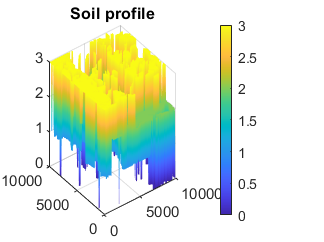

figure(2);
surf(XM,YM,soil);
title("Soil profile");
shading interp;
cmap = colormap;
colorbar;

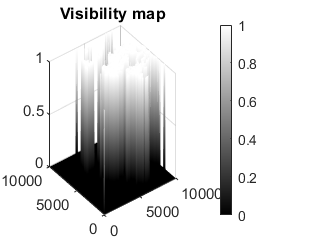

figure(3);
surf(XM,YM,vis);
title("Visibility map");
shading interp;
colormap gray;
colorbar;

## High Resolution Data (Interpolated)

%% X and Y matrices with 1 meter intervals
global Xm Ym;

xv = [0:1:9950];
Xm = zeros(length(xv)); % high resolution x
for i=1:length(xv)
    Xm(i,:) = xv;
end

yv = [0:1:9950]';
Ym = zeros(length(yv)); % high resolution y
for i=1:length(yv)
    Ym(:,i) = yv;
end

clear xv yv;

% High-res Elevation data
global Zm;
Zm = interp2(XM, YM, ZM, Xm, Ym); % high resolution z

% High-res soil data
global soilm;
soilm = interp2(XM, YM, soil, Xm, Ym); % high resolution soil map

% High-res visibility data
global vism;
vism = interp2(XM, YM, vis, Xm, Ym); % high resolution visibility map

% figure(4);
% surf(Zm(1:2500, 1:2500));
% %caxis(lims);
% shading interp;
% colorbar;

## Dynamic Programming

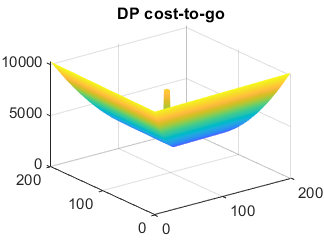

% Implement DP here
% Assuming obtained cost-to-go map as follows:
costDP = zeros(size(ZM));
lastMin = -1;
for i=200:-1:1
    vecLen = 200 - (i-1);
    maxPt = lastMin + vecLen;
    minPt = lastMin + 1;
    vec = [minPt:maxPt];
    costDP(i:200,i) = vec';
    costDP(i,i:200) = vec;
    lastMin = mean([minPt, maxPt]);
end

% Adding random peaks
costDP(170:175, 20:25) = 9000;
costDP(20:25, 170:175) = 9000;
costDP(75:80,75:80) = 9000;

surf(costDP);
title("DP cost-to-go");
colormap(cmap);
shading interp;

clear lastMin vecLen vec maxPt minPt cmap lims;

## High Resolution DP cost-to-go (Interpolated)

global costDPm;
costDPm = interp2(XM, YM, costDP, Xm, Ym);

%spoofing an obstacle
%costDPm(100:200,100:200) = 15000;

## MPC Parameters

%%%%%%%%%%%%%% MPC parameters %%%%%%%%%%%%%%
global Np;
global w1 w2 w3 w4 w5 w6;  % Individual cost weights

% Prediction horizon
Np = 25;    

% Cost weights
w1 = 1;
w2 = 1;
w3 = 1;
w4 = 1;
w5 = 1;
w6 = 0.1;

% Input constraint limits
delta_max = (pi/3);
delta_dot_max = delta_max/0.15;

% fmincon options
options = optimoptions('fmincon','Display','off');

## Model Predictive Controller

%%%%%%%%%%%%%% Inequality constraint matrix A %%%%%%%%%%%%%%
A = zeros(2*(Np-1)+2*(Np-3), Np);
% Constraints on max delta
for i=1:(Np-1)
    A(i,i) = -1;
    A(i,i+1) = 1;
end
for i=Np:2*(Np-1)
    A(i,i-Np+1) = 1;
    A(i,i-Np+2) = -1;
end
% Constraints on max delta_rate
for i=2*(Np-1)+1:2*(Np-1)+(Np-3)
    A(i,i-2*(Np-1)+3) = 1;
    A(i,i-2*(Np-1)+2) = -1;
    A(i,i-2*(Np-1)+1) = -1;
    A(i,i-2*(Np-1)) = 1;
end
for i=2*(Np-1)+(Np-3)+1:size(A,1)
    A(i,i-(3*Np-5)+3) = -1;
    A(i,i-(3*Np-5)+2) = 1;
    A(i,i-(3*Np-5)+1) = 1;
    A(i,i-(3*Np-5)) = -1;
end

%%%%%%%%%%%%%% Inequality constraint matrix B (delta max/ max steering input) %%%%%%%%%%%%%%
B = ones(2*(Np-1)+2*(Np-3),1);
B(1:Np-1) = delta_max*B(1:Np-1);
B(Np:2*(Np-1)) = -delta_max*B(Np:2*(Np-1));
B(2*(Np-1)+1:2*(Np-1)+(Np-3)) = delta_dot_max*B(2*(Np-1)+1:2*(Np-1)+(Np-3));
B(2*(Np-1)+(Np-3)+1:size(B,1)) = -delta_dot_max*B(2*(Np-1)+(Np-3)+1:size(B,1));

%%%%%%%%%%%%%% Running MPC for the whole journey %%%%%%%%%%%%%%
% Storing control history
u_opt = zeros(10*size(Xm,1),1);   % Declaring extra large vector because we don't know number of control inputs required
num_u = 0;  % will update from loop

% Storing optimal state trajectory
x_traj = zeros(size(u_opt));
y_traj = zeros(size(u_opt));

% Starting at (0,0)
global x_start y_start x_end y_end;
x_start = Xm(1,1);
y_start = Ym(1,1);

while ((x_start ~= Xm(end,end)) && (y_start ~= Ym(end,end))) && (num_u <= 1000)% 0.4*size(u_opt,1))
    tic

    % Possible delta_s, x and y
    pos_u = [0: pi/180: 359*pi/180];    % possible heading angles in radians
    pos_xN = x_start + Np*cos(pos_u);   % Np is the radius at Nth step
    pos_yN = y_start + Np*sin(pos_u);

    %% Filter out out-of-bound x & y
    % Finding indices of infeasible x and y
    notpos_xN_ind = (pos_xN < x_min) | (pos_xN > x_max);
    notpos_yN_ind = (pos_yN < y_min) | (pos_yN > y_max);
    % Assigning NaN to x values based on infeasible x & y indices
    pos_xN(notpos_xN_ind) = NaN;
    pos_xN(notpos_yN_ind) = NaN;
    % Assigning NaN to y values based on infeasible x & y indices
    pos_yN(notpos_xN_ind) = NaN;
    pos_yN(notpos_yN_ind) = NaN;
    % Removing NaN pairs from the vectors representing possible x & y pairs 
    pos_xN = pos_xN(~isnan(pos_xN));
    pos_yN = pos_yN(~isnan(pos_yN));
    % Find (xN, yN) pair with minimum cost-to-go
    [minCost, I] = min(costDPm(sub2ind(size(costDPm), round(pos_xN)+1, round(pos_yN)+1))); % Assuming cost-to-go at (32.28, 43.31) should be very close to that at (32,43)
    x_end = pos_xN(I);
    y_end = pos_yN(I);
  
    %% Run fmincon for this kth step
    u_init = atan((y_end - y_start)/(x_end - x_start)); % Calculating initial u for faster fmincon convergence
    u_cal = fmincon(@mpcCostFunction, u_init*ones(Np,1), [], [], [], [], [], [], [], options);
    num_u = num_u + 1;
    u_opt(num_u) = u_cal(1);

    % Update x_start and y_start
    x_start = x_start + 1*cos(u_opt(num_u));    % delta_s for the 1st step is equal to r = 1 meter
    y_start = y_start + 1*sin(u_opt(num_u));

    % Saving trajectory for later visualization
    x_traj(num_u+1) = x_start;
    y_traj(num_u+1) = y_start;

    toc
    fprintf("num_u = %d, ", num_u);
    fprintf("x = %0.2f, ", x_start);
    fprintf("y = %0.2f\n", y_start);
%     if (mod(num_u,100) == 0)
%         fprintf("num_u = %d\n", num_u);
%     end
end
clear pos_xN pos_yN notpos_xN_ind notpos_yN_ind xNyN_pairs pos_u;


plot(x_traj(1:326),y_traj(1:326));

function J = mpcCostFunction(u, costDPm)
global x_start y_start x_end y_end;
global x_min y_min x_max y_max;
global Xm Ym;
global Zm soilm vism;
global w1 w2 w3 w4 w5 w6;
global Np;
global costDPm;

    % vectors to store resultant x & y trajectories using control seq u
    x = zeros(Np+1,1);
    y = zeros(Np+1,1);

    % Initialize x and y
    x(1) = x_start;
    y(1) = y_start;

    for i=1:Np
        % Calculating the next x & y (at k+1) 
        tau = (x(i) - x_start)*cos(u(i)) + (y(i) - y_start)*sin(u(i));
        delta_s = sqrt((2*(i-1)+1) + (tau^2)) - tau;    % k starts from 0 in this formula
        x(i+1) = x(i) + delta_s*cos(u(i));
        y(i+1) = y(i) + delta_s*sin(u(i));

        % Checking for x(i+1) and y(i+1) to be within bounds
        if (x(i+1) < x_min || x(i+1) > x_max) || (y(i+1) < y_min || y(i+1) > y_max)
            J = inf;
            return;
        end
    end

    % Calculating the z profile
    z = Zm(sub2ind(size(Zm), round(x)+1, round(y)+1));  % Interpolation was very expensive

    % Distance cost
    J_dist = sum(sqrt((x(2:end)- x(1:end-1)).^2 + (y(2:end)- y(1:end-1)).^2 + (z(2:end)- z(1:end-1)).^2));

    % Soil cost
    soil_r = soilm(sub2ind(size(soilm), round(x)+1, round(y)+1));  % Soil rating (interpolation was very expensive)
    soil_r = ones(size(soil_r))./soil_r;
    J_soil = sum(soil_r(2:end) + soil_r(1:end-1));

    % Elevation cost
    J_elev = sum(abs(z(2:end) - z(1:end-1)));

    % TODO: Obstacle cost
    % J_obs

    % Visibility cost
    J_vis = sum(vism(sub2ind(size(vism), round(x)+1, round(y)+1)));
    
    % Terminal cost

    %getting the exact terminal cost value at the point x(end),y(end)
    x_dp = ceil(x(end));
    y_dp = ceil(y(end));
    J_dp = costDPm(x_dp,y_dp);

    %J_dp = sqrt((x(end) - x_end)^2 + (y(end) - y_end)^2);

    % Total MPC cost
    J = w1*J_dist + w2*J_soil + w3*J_elev + w5*J_vis + w6*J_dp;    % TODO: Add obstacle cost to this
end